Wizualizacja najprostszych metod numerycznego rozwiązywania równania różniczkowego: otwartej i zamkniętej metody Eulera:


clear all;
close all;
clc;

y=@(t) exp(-(t-1).^2);
y_prim=@(t,y) (-2*t+2)*y;
H=0.2;

t0=1/2;
tk=3/2;

t=linspace(t0,tk,1e4);
tn=0.7;
tnp1=tn+H;

y_dokl=y(t);
a_tn=y_prim(tn, y(tn));
b_tn=y(tn)-a_tn*tn;
a_tnp1=y_prim(tnp1, y(tnp1));
b_tnp1=y(tnp1)-a_tnp1*tnp1;
b_tnp1_pararel=y(tn)-a_tnp1*tn;

styczna_tn=a_tn*t+b_tn;
styczna_tnp1=a_tnp1*t+b_tnp1;
pararel_tnp1=a_tnp1*t+b_tnp1_pararel;


figure(1)
hold on
plot(t,y_dokl, 'b', t, styczna_tn, '--r')

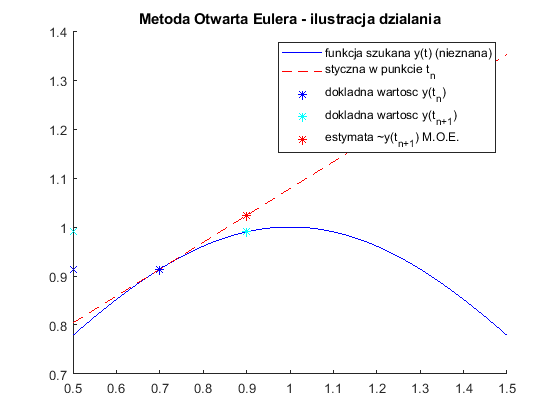

plot(tn, y(tn), 'b*', tnp1, y(tnp1), 'c*', tnp1, y(tn)+H*a_tn, 'r*')
title 'Metoda Otwarta Eulera - ilustracja działania'
legend('funkcja szukana y(t) (nieznana)', 'styczna w punkcie t_n', 'dokładna wartość y(t_n)', 'dokładna wartość y(t_{n+1})', 'estymata ~y(t_{n+1}) M.O.E.')


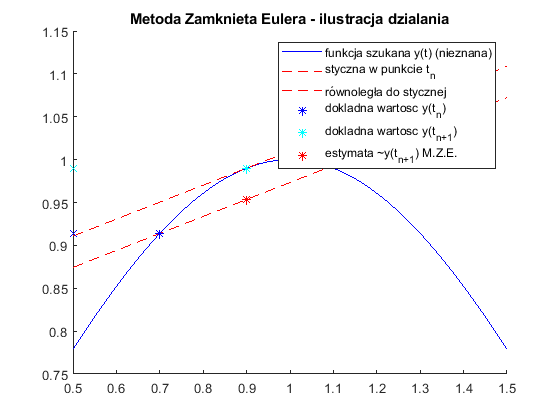

figure(2)
hold on
plot(t,y_dokl, 'b', t, styczna_tnp1, '--r', t, pararel_tnp1, '--r')
plot(tn, y(tn), 'b*', tnp1, y(tnp1), 'c*', tnp1, y(tn)+H*a_tnp1, 'r*')
title 'Metoda Zamknięta Eulera - ilustracja działania'
legend('funkcja szukana y(t) (nieznana)', 'styczna w punkcie t_n', 'równoległa do stycznej', 'dokładna wartość y(t_n)', 'dokładna wartość y(t_{n+1})', 'estymata ~y(t_{n+1}) M.Z.E.')